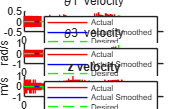

clc;
clear;
load("C:\Users\Antony\Documents\GitHub\ME423\Lab_4\positiondata.mat")
fontsiz = 6;
t = data(1,:);
dt = t(2) - t(1);

% Desired position
theta1_dot_d = data(2,:);  
theta2_dot_d = data(3,:);  
theta3_dot_d = data(4,:);

% Actual position
theta1_dot_a = data(5,:);  
theta2_dot_a = data(6,:);  
theta3_dot_a = data(7,:);

%% --- (Optional) smooth ONLY actual position before differentiating ---
% Small window is usually enough; increase if encoder noise is nasty
theta1_dot_as = smoothdata(theta1_dot_a,'gaussian',10);
theta2_dot_as = smoothdata(theta2_dot_a,'gaussian',10);
theta3_dot_as = smoothdata(theta3_dot_a,'gaussian',10);

%% --- VELOCITY ---
theta1_dot_dot_d = [0 diff(theta1_dot_d)/dt];
theta2_dot_dot_d = [0 diff(theta2_dot_d)/dt];
theta3_dot_dot_d = [0 diff(theta3_dot_d)/dt];

theta1_dot_dot_a = [0 diff(theta1_dot_a)/dt];
theta2_dot_dot_a = [0 diff(theta2_dot_a)/dt];
theta3_dot_dot_a = [0 diff(theta3_dot_a)/dt];

theta1_dot_dot_as = [0 diff(theta1_dot_as)/dt];
theta2_dot_dot_as = [0 diff(theta2_dot_as)/dt];
theta3_dot_dot_as = [0 diff(theta3_dot_as)/dt];

%% --- ACCELERATION ---
theta1_ddot_d = [0 diff(theta1_dot_dot_d)/dt];
theta2_ddot_d = [0 diff(theta2_dot_dot_d)/dt];
theta3_ddot_d = [0 diff(theta3_dot_dot_d)/dt];

theta1_ddot_a = [0 diff(theta1_dot_dot_a)/dt];
theta2_ddot_a = [0 diff(theta2_dot_dot_a)/dt];
theta3_ddot_a = [0 diff(theta3_dot_dot_a)/dt];

theta1_ddot_as = [0 diff(theta1_dot_dot_as)/dt];
theta2_ddot_as = [0 diff(theta2_dot_dot_as)/dt];
theta3_ddot_as = [0 diff(theta3_dot_dot_as)/dt];

% --- JERK ---
theta1_jerk_d = [0 diff(theta1_ddot_d)/dt];
theta2_jerk_d = [0 diff(theta2_ddot_d)/dt];
theta3_jerk_d = [0 diff(theta3_ddot_d)/dt];

theta1_jerk_a = [0 diff(theta1_ddot_a)/dt];
theta2_jerk_a = [0 diff(theta2_ddot_a)/dt];
theta3_jerk_a = [0 diff(theta3_ddot_a)/dt];

theta1_jerk_as = [0 diff(theta1_ddot_as)/dt];
theta2_jerk_as = [0 diff(theta2_ddot_as)/dt];
theta3_jerk_as = [0 diff(theta3_ddot_as)/dt];

%% --- PLOTS (Velocity) ---
figure();
subplot(3,1,1)
hold on;
plot(t, theta1_dot_dot_a, "red","DisplayName","Actual")
plot(t, theta1_dot_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta1_dot_dot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta1 velocity")
ylabel("rad/s")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, theta2_dot_dot_a, "red","DisplayName","Actual")
plot(t, theta2_dot_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta2_dot_dot_d, "green","LineStyle","--","DisplayName","Desired")
ylabel("rad/s")
subtitle("\theta3 velocity")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, theta3_dot_dot_a, "red","DisplayName","Actual")
plot(t, theta3_dot_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta3_dot_dot_d, "green","LineStyle","--","DisplayName","Desired")
title("z velocity")
ylabel("m/s")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

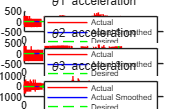



%% --- PLOTS (Acceleration) ---
figure();
subplot(3,1,1)
hold on;
plot(t, theta1_ddot_a, "red","DisplayName","Actual")
plot(t, theta1_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta1_ddot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta1 acceleration")
ylabel("rad/s^2")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, theta2_ddot_a, "red","DisplayName","Actual")
plot(t, theta2_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta2_ddot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta2 acceleration")
ylabel("rad/s^2")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, theta3_ddot_a, "red","DisplayName","Actual")
plot(t, theta3_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta3_ddot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta3 acceleration")
ylabel("rad/s^2")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

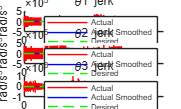


%% --- PLOTS (Jerk) ---
figure();
subplot(3,1,1)
hold on;
plot(t, theta1_jerk_a, "red","DisplayName","Actual ")
plot(t, theta1_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta1_jerk_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta1 jerk")
ylabel("rad/s^3")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize =fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, theta2_jerk_a, "red","DisplayName","Actual")
plot(t, theta2_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta2_jerk_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta2 jerk")
ylabel("rad/s^3")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, theta3_jerk_a, "red","DisplayName","Actual")
plot(t, theta3_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta3_jerk_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta3 jerk")
ylabel("rad/s^3")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;